## Paulina Guiset Rodríguez López 

## Matrícula 202156221

# TAREA 3

## Problema 3.31 Libro Nieves

Resuelva el sistema tridiagonal


$$\begin{array}{l}
3x_1 -2x_2 +0x_3 =1\ldotp 0\\
x_1 +5x_2 -0\ldotp 2x_3 =5\ldotp 8\\
0x_1 +4x_2 +7x_3 =11\ldotp 0
\end{array}$$


por el método de Thomas.

A=[3 -2 0;
   1 5 -0.2;
   0 4 7];
b=[1;5.8;11];

Sol_331=Thomas(A,b)

Sol_331 =     1.0000
    1.0000
    1.0000


## Problema 3.1 Libro Nieves

En una columna de cinco platos, se requiere absrober benceno que está contenido en una corriente de gas V, con un aceite L que circula a contracorriente del gas. Considérese que el benceno transferido no altera sustancialmente el número de moles de V y L fluyendo a contracorriente, que la relación de equilibrio está dada por la ley de Henrry($y=\mathrm{mx}$) y que la columna opera a régimen permanente. Calcule la composición del benceno en cada plato.

Datos:


$$\begin{array}{l}
V=100\;\frac{\mathrm{moles}}{\mathrm{min}}\\
L=500\;\frac{\mathrm{moles}}{\mathrm{min}}\\
y_0 =0\ldotp 09\;\mathrm{fracción}\;\mathrm{mol}\;\mathrm{de}\;\mathrm{benceno}\;\mathrm{en}\;V\ldotp \\
x_0 =0\ldotp 0\;\mathrm{fracción}\;\mathrm{molar}\;\mathrm{de}\;\mathrm{benceno}\;\mathrm{en}\;L\left(\mathrm{el}\;\mathrm{aceite}\;\mathrm{entra}\;\mathrm{por}\;\mathrm{el}\;\mathrm{domo}\;\mathrm{sin}\;\mathrm{benceno}\right)\\
m=0\ldotp 12
\end{array}$$


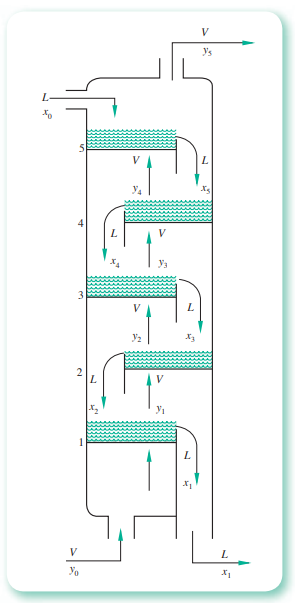

Los balances de materia para el benceno en cada plato son:

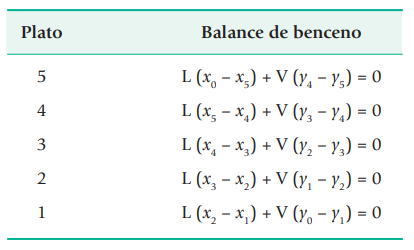

Al sustituir la información que se tiene, las consideraciones hechas y rearreglando las ecuaciones, se llega a:


$$\begin{array}{l}
512x_5 -12x_4 +0{\ldotp 00x}_3 +0\ldotp 00x_2 +0\ldotp 0x_1 =0\\
500x_5 -512x_4 +12x_3 +0\ldotp 00x_2 +0\ldotp 00x_1 =0\\
0{\ldotp 00x}_5 +500x_4 -512x_3 +12x_2 +0\ldotp 00x_1 =0\\
0\ldotp 00x_5 +0\ldotp 00x_4 +500x_3 -512x_2 +12x_1 =0\\
0\ldotp 0x_5 +0\ldotp 0x_4 +0{\ldotp 00x}_3 -500x_2 +512x_1 =9
\end{array}$$


Resolviendo se obtienen los siguientes resultados:

A=[512 -12 0 0 0;
   500 -512 12 0 0;
   0 500 -512 12 0;
   0 0 500 -512 12;
   0 0 0 -500 512];
b=[0 0 0 0 9];
b=b';

Sol_31=Thomas(A,b)

Sol_31 =     0.0000
    0.0000
    0.0000
    0.0004
    0.0180


## Problema 3.2 Libro Nieves

Un bloque de 10kg está suspendido de un sistema de cables y anillos, como se muetra en la figura.

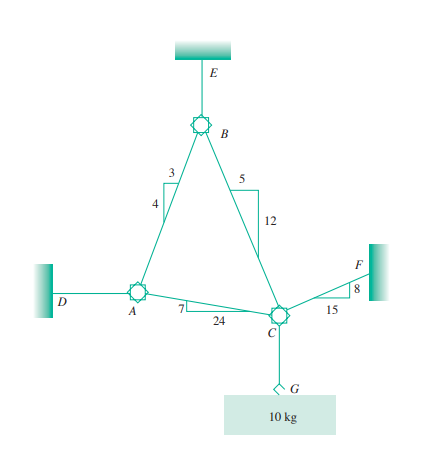

Determinen la tensión en cada cable del sistema.

***Solución***

Los diagramas de cuerpo libre relevantes son:

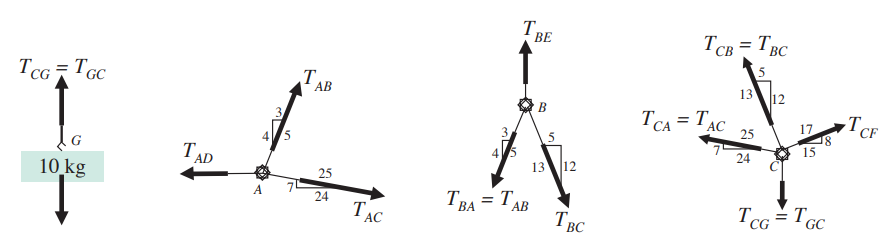

Para el equilibrio del bloque G, escribimos


$$\sum F_y =0\;\;\;\;T_{\mathrm{CG}} -10g=0;\;T_{\mathrm{CG}} =98\ldotp 1N$$


donde $g=9\ldotp 81\;\frac{m}{s^2 }$

De los tres diagramas de cuerpo libre, para cada uno de los anillos tenemos un total de seis incognitas:$T_{\mathrm{AB}} ,T_{\mathrm{AC}} ,{\;T}_{\mathrm{AD}} ,T_{\mathrm{BC}} ,T_{\mathrm{BE}} \;y\;T_{\mathrm{CF}} \ldotp$Además, para cada diagrama podemos escribir dos ecuaciones de equilibrio de fuerzas independientes y obtener un total de seis ecuaciones independientes en seis incognitas. Por lo tanto, las seis incógnitas pueden determinarse. Para el equilibrio de los anillos como se muestra en su diagrama de cuerpo libre, se obtiene.

*Anillo A*


$$\begin{array}{l}
\sum F_x =0;\;\;\frac{3}{5}T_{\mathrm{AB}} +\frac{24}{25}T_{\mathrm{AC}} -T_{\mathrm{AD}} =0\\
\sum F_y =0;\;\;\frac{4}{5}T_{\mathrm{AB}} +\frac{7}{25}T_{\mathrm{AC}} =0
\end{array}$$


*Anillo B*


$$\begin{array}{l}
\sum F_x =0;\;-\frac{3}{5}T_{\textrm{AB}} +\frac{5}{13}T_{\textrm{BC}} =0\\
\sum F_y =0;\;-\frac{4}{5}T_{\mathrm{AB}} +\frac{12}{3}T_{\mathrm{BC}} +T_{\mathrm{BE}} =0
\end{array}$$


*Anillo C*


$$\begin{array}{l}
\sum F_x =0;\;-\frac{24}{25}T_{\textrm{AC}} -\frac{5}{13}T_{\textrm{BC}} +\frac{15}{17}T_{\mathrm{CF}} =0\\
\sum F_y =0;\;\;\frac{7}{25}T_{\mathrm{AC}} +\frac{12}{13}T_{\mathrm{BC}} +\frac{8}{17}T_{\mathrm{CF}} =98\ldotp 1
\end{array}$$


Las seis ecuaciones anteriores pueden escribirse en la forma de un sistema de ecuaciones lineales

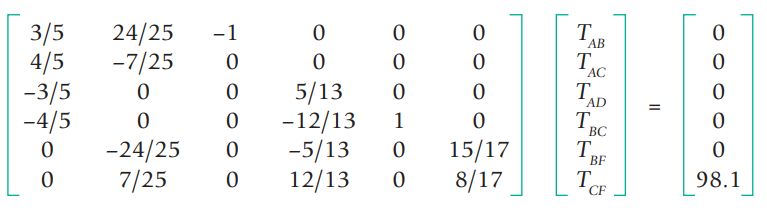

A=[3/5 24/25 -1 0 0 0;
   4/5 -7/25 0 0 0 0;
   -3/5 0 0 5/13 0 0;
   -4/5 0 0 -12/13 1 0;
   0 -24/25 0 -5/13 0 15/17;
   0 7/25 0 12/13 0 8/17];
b=[0 0 0 0 0 98.1]';

X_sol32=Cramer(A,b)

X_sol32 =   24.385653409090917
  69.673295454545453
  81.517755681818187
  38.041619318181816
  54.623863636363637
  92.386789772727255


## Problema 3.3 Libro Nieves

Determine las concentraciones molares de una mezcla de cinco componentes en solución a partir de los siguientes datos espectrofotométricos.

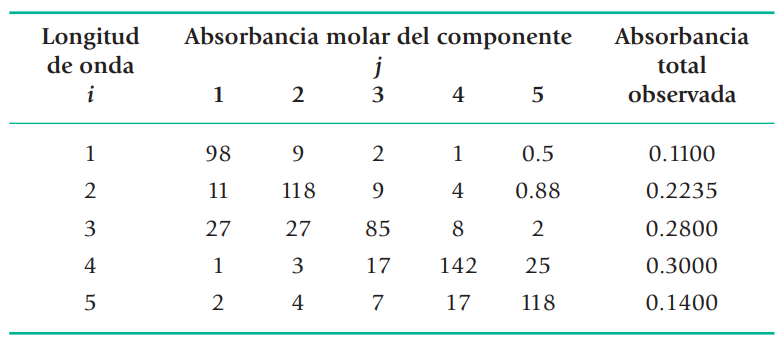

Asúmase que la longitud de la trayectoria óptica es unitaria y que el solvente no absorbe a estas longitudes de onda

**Solución**

Si se considera que se cumple la Ley de Beer, entonces a una longitus de onda dada, $i$


$$A_{\mathrm{TOTi}} =\sum_{j=1}^5 \varepsilon_{i,j} C_i$$


Donde:


$$\begin{array}{l}
A_{\mathrm{TOTi}} \;\mathrm{es}\;\mathrm{la}\;\mathrm{absorbancia}\;\;\mathrm{total}\;\mathrm{observada}\;a\;\mathrm{la}\;\mathrm{longitus}\;\mathrm{de}\;\mathrm{onda}\;i\ldotp \\
\varepsilon_{i,j} \;\mathrm{es}\;\mathrm{la}\;\mathrm{absorbancia}\;\mathrm{molar}\;\mathrm{del}\;\mathrm{componente}\;j\;a\;\mathrm{la}\;\mathrm{longitus}\;\mathrm{de}\;\mathrm{onda}\;i\\
C_j \;\mathrm{es}\;\mathrm{la}\;\mathrm{concentración}\;\mathrm{molar}\;\mathrm{del}\;\mathrm{componete}\;j\;\mathrm{en}\;\mathrm{la}\;\mathrm{mezcla}\ldotp 
\end{array}$$


Al sustiruir los valores de la tabla se obtiene:


$$\begin{array}{l}
98C_1 +9C_2 +2C_3 +C_4 +0\ldotp 5C_5 =0\ldotp 1100\\
11C_1 +118C_2 +9C_3 +4C_4 +0\ldotp 88C_5 =0\ldotp 2235\\
27C_1 +27C_2 +85C_3 +8C_4 +2C_5 =0\ldotp 2800\\
C_1 +3C_2 +17C_3 +142C_4 +25C_5 =0\ldotp 3000\\
2C_1 +4C_2 +7C_3 +17C_4 +118C_5 =0\ldotp 1400
\end{array}$$


Un sistema de ecuaciones lineales con matriz coeficiente dominate. Esto suguiere resolver con el método de Gauss-Seidel.

*Solución:*

A=[98 9 2 1 0.5;
   11 118 9 4 0.88;
   27 27 85 8 2;
   1 3 17 142 25;
   2 4 7 17 118];
b=[0.1100 0.2235 0.2800 0.3000 0.1400]';
x0=[0 0 0 0 0]';

[E_33,X1_33,err_33]=Gaus_Seidel(A,b,x0,5,1e-6)

E_33 = 'La aproximación está dentro de la tolerancia indicada'

X1_33 =    0.000909983894900
   0.001569466336323
   0.002332534448280
   0.001663618394441
   0.000739770449334


err_33 =      7.491292996057499e-07


## Problema 3.5 Libro Nieves

Con los datos del dagrama siguiente (donde los porcentajes están dados en peso), encuentre posibles valores de las corrientes $M_1 ,M_2 ,M_3 ,y\;M_4 \ldotp$

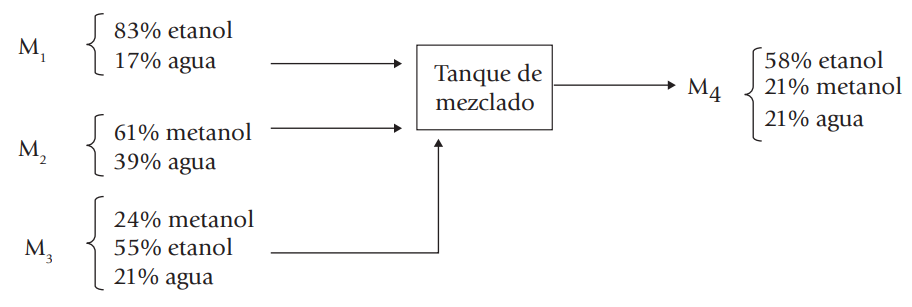

**Solución**

Mediante balances de materia por componente y global, se tiene:

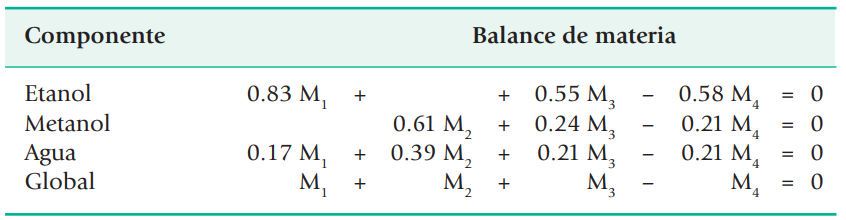

Hay que observar que sólo se tienen tres ecuaciones linealmente independietes, pues la ecuación del balance global de materia es la suma de las otras tres. Por ser el sistema homogéneo es consistente, y como el rango de la matriz coeficiente es menor que el número de incógnitas, el sistema tiene un número infinito de soluciones. Fijando una base de cálculo, por ejemplo $M_4 =100\;\mathrm{kg}$, se obtiene el sistema:


$$\begin{array}{l}
0\ldotp 83M_1 +0\ldotp 00M_2 +0\ldotp 55M_3 =58\\
0\ldotp 00M_1 +0\ldotp 61M_2 +0\ldotp 24M_3 =21\\
0\ldotp 17M_1 +0\ldotp 39M_2 +0\ldotp 21M_3 =21
\end{array}$$


Cuya solución es:

A=[0.83 0.00 0.55;
   0.00 0.61 0.24;
   0.17 0.39 0.21];
b=[58 21 21]';

X_35=Cramer(A,b)

X_35 =   19.014084507042256
   4.225352112676050
  76.760563380281710
